# Analyzing Your Labeled Data

This live script includes the code shown in the prior video and more. Work through the sections below to gain a better understanding of the fastener dataset. 

## Load the Ground Truth

We've labeled the images in the fastener dataset and provided the ground truth for you in the course files. The images were labeled using the Image Labeler App that you saw previously. The mat-file `fastenerTrainGT `contains a variable with the same name that is the ground truth object. 

Run this section to load the ground truth and create the image and box label datastores.

load fastenerTrainGT.mat fastenerTrainGT
fastenerTrainGT

fastenerTrainGT =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [4×5 table]
           LabelData: [367×4 table]


The function below creates an image and box label datastore for object detection.

[imds, blds] = objectDetectorTrainingData(fastenerTrainGT);

### View summary of object labels and the LabelData

It is good practice to look at the number of objects and the number of images containing those objects. If you notice that some classes have few objects and/or images, you may need to collect more images or use techniques like data augmentation. Data augmentation is covered in course 3 of this specialization. 

countEachLabel(blds)

ans = 4×3 table
    Label     Count    ImageCount
    ______    _____    __________

    Nail       222        170    
    Nut        211        167    
    Screw      291        202    
    Washer     173        140    


## **Create a Table for Analyzing Bounding Boxes**

The data in the box label datastore is structured for the model training functions you'll learn later. The `createBoundingBoxTable` is a helper function located at the bottom of the script that reorganizes the data into a table for analysis and visualization.

bboxes = createBoundingBoxTable(blds)

bboxes = 897×3 table
    ImgIdx              BBox              Label 
    ______    ________________________    ______

       1      337    206     57     57    Washer
       2      332    214     56     58    Washer
       3      336    217     57     55    Washer
       4      333    221     56     56    Washer
       5      322    218     58     54    Washer
       6      334    213     57     55    Washer
       7      330    216     56     55    Washer
       8      326    219     57     58    Washer
       9      339    220     57     56    Washer
      10      318    200     87     88    Washer
      11      321    193     89     89    Washer
      12      318    204     87     86    Washer
      13      316    205     88     87    Washer
      14      320    204     88     88    Washer
      15      318    201     90     88    Washer
      16      319    196     88     88    W

### Add area and aspect ratio

The bounding box coordinates for each object is a 1x4 vector. The first two elements are the x and y locations of the upper left corner of the box. The third and fourth elements are the width and height of the bounding box. The code below uses the width and height to calculate the area and aspect ratio of the boxes and adds these quantities to the table.

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 897×5 table
    ImgIdx              BBox              Label     Area    AspectRatio
    ______    ________________________    ______    ____    ___________

       1      337    206     57     57    Washer    3249            1  
       2      332    214     56     58    Washer    3248      0.96552  
       3      336    217     57     55    Washer    3135       1.0364  
       4      333    221     56     56    Washer    3136            1  
       5      322    218     58     54    Washer    3132       1.0741  
       6      334    213     57     55    Washer    3135       1.0364  
       7      330    216     56     55    Washer    3080       1.0182  
       8      326    219     57     58    Washer    3306      0.98276  
       9      339    220     57     56    Washer    3192       1.0179  
      10      31

## Create Visualizations and Analyze Bounding Boxes

### Create a scatter plot

A scatter plot is a good way to determine if there is a relationship between area and aspect ratio. Here, we use a group scatter plot since there are only four categories. Notice that washers and nuts have distinct clusters. However, the area and aspect ratios of bounding boxes for nails and screws vary significantly. This is because orientation impacts the bounding size for these two classes.

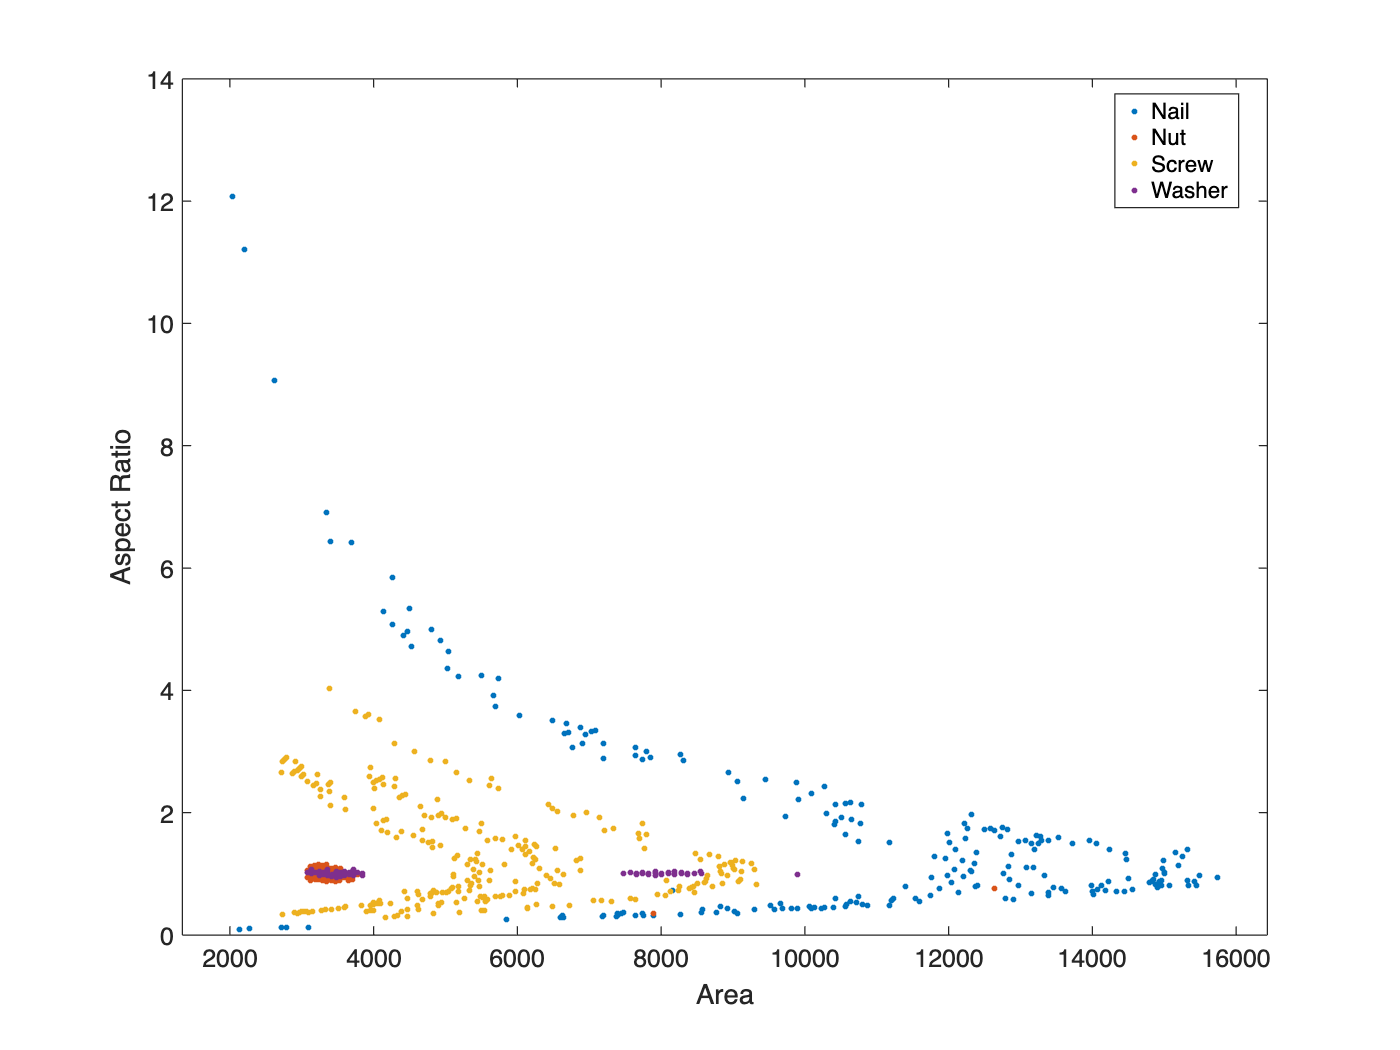

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

### Create box plots of aspect ratios for each class

A box plot is a compact way to visualize the distribution of a variable. Here, the distribution of the aspect ratios for each class is shown. 

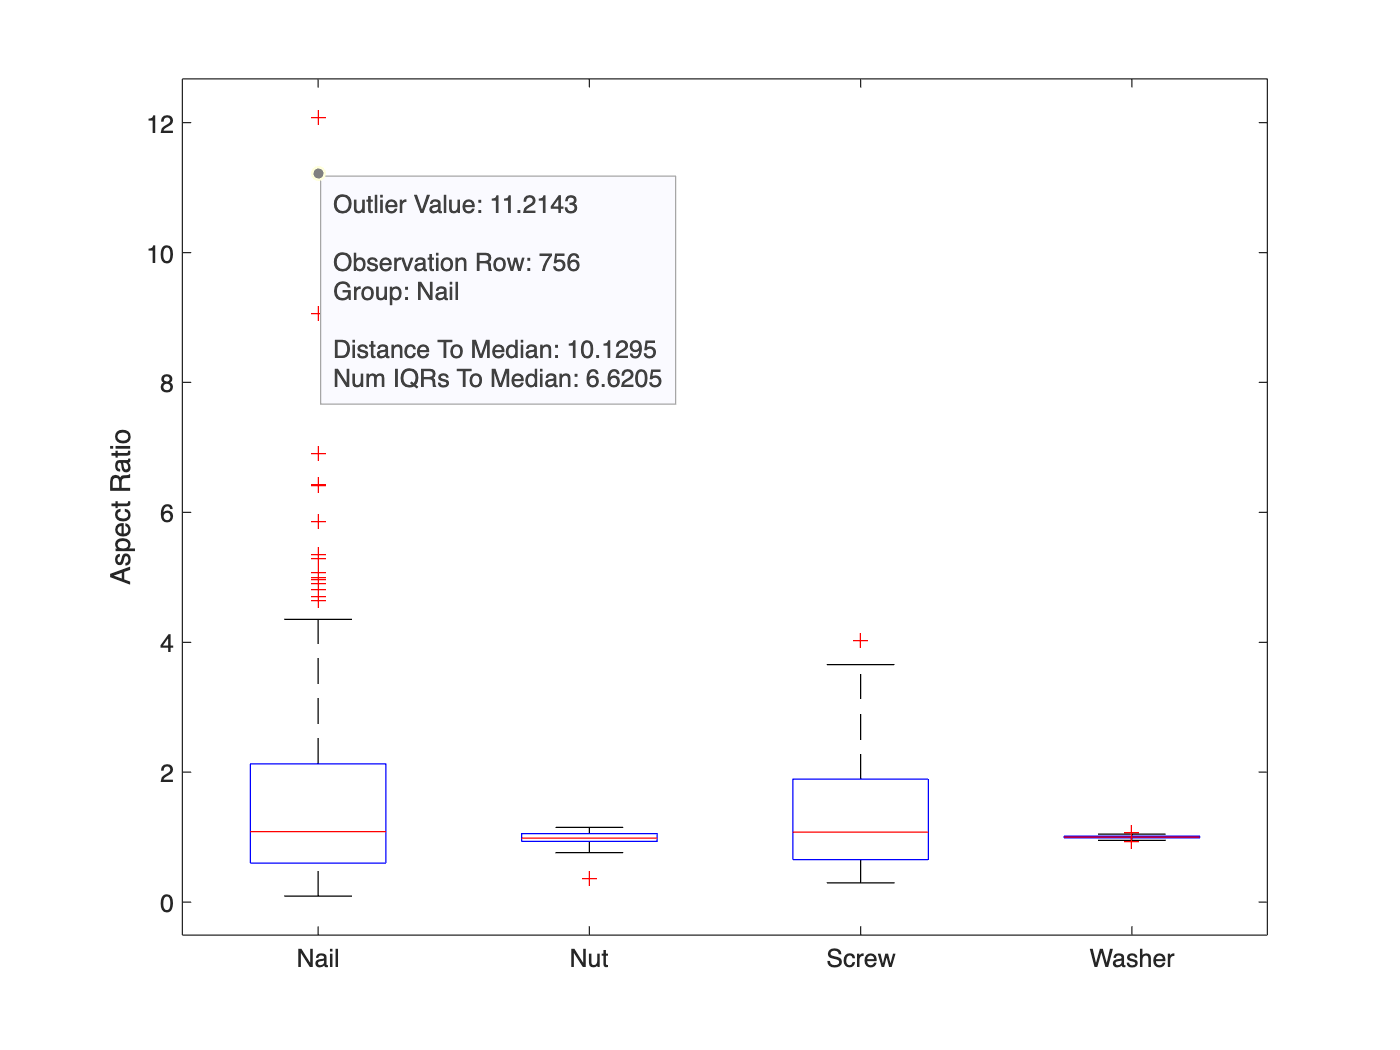

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

### You try: Create a box plot of area for each class

It makes sense that nuts and washers will have aspect ratios near 1. Visualizing the distribution of areas will tell you if there are different sizes of these objects in the images.

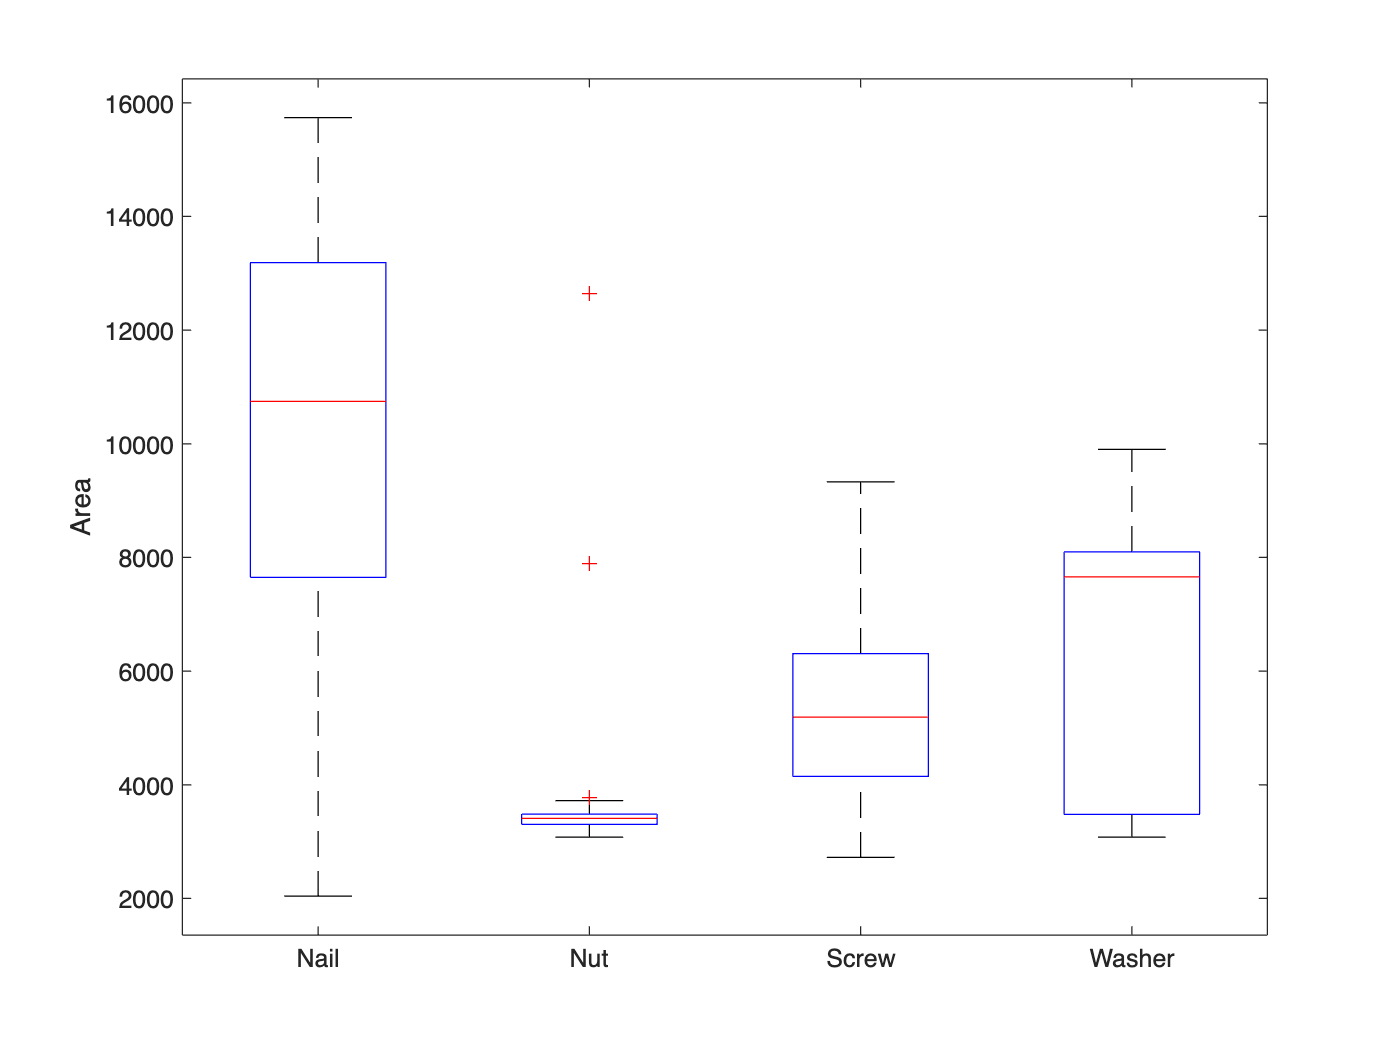

boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

## Investigate Selected Outliers

Outliers can indicate many different things and are not necessarily bad. In the video, you saw outliers that were normal nails, but at orientations that rarely occurred in the dataset. You also saw an outlier that was a mislabeled image. 

Use the drop-down menus below to find the outliers for a specific class and variable. `displayOutlierImage `is a helper function at the bottom of the script that uses your selections to display the outlier object or message to help you set the controls. 

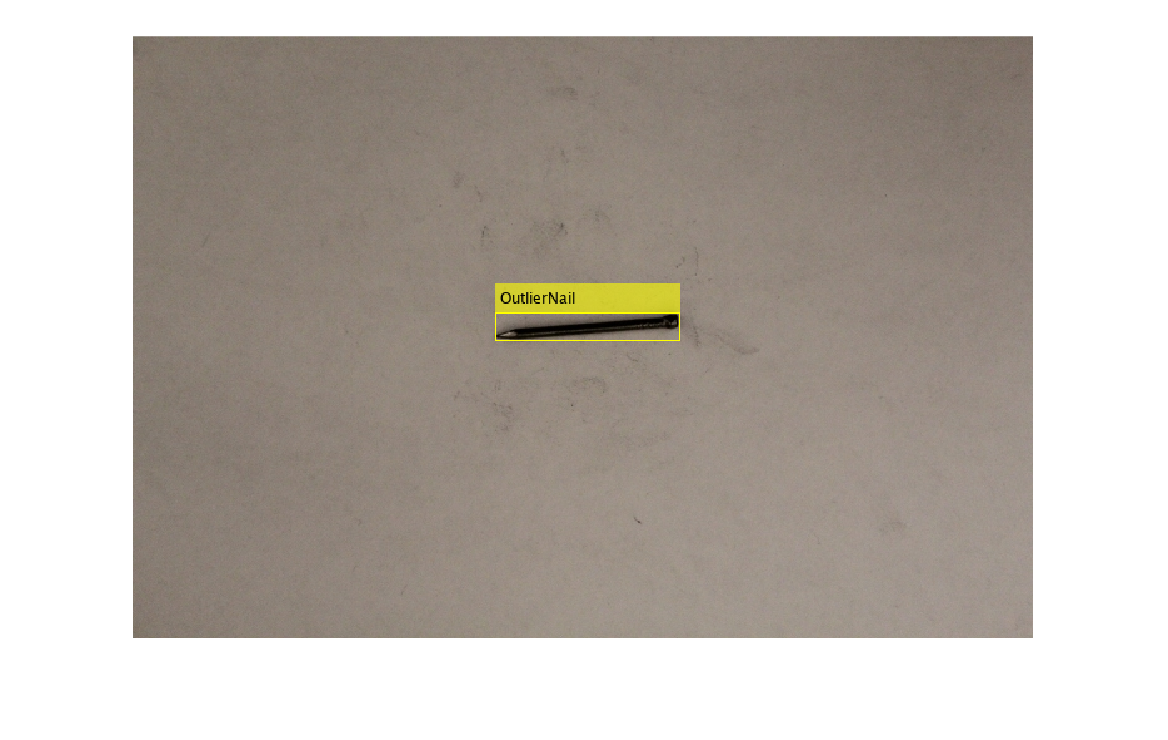

class = "Nail";
variable = "AspectRatio";
outlier2view = 2;
displayOutlierImage(bboxes, class, variable, outlier2view, imds);

## Closing remarks

By doing this analysis, you found a few mislabeled images that you can fix. You do not need to fix them for this course, but in your applications, you should load your ground truth into the Image Labeler app to fix there errors. Once fixed, there is nothing that immediately stands out as a concern for training an object detection model with this dataset.

- The distribution of images and objects is fairly equal amongst the classes.

- This distribution of bounding box areas is less than an order of magnitude. 

- Most outliers are normal objects at orientations that rare in the dataset.

This does not mean you'll be successful in training a model. A difficult question to answer is: how many images do you need? The number of objects and images you need to train an object detection model depends on many variables. In applications where the lighting, background, and perspective don't vary much, you likely won't need as much data compared to datasets with high variability. For the fastener dataset, the images are taken from the same perspective with the same background. There are also only a few different types of each fastener, so a model does not need to learn to detect a wide array of nails and screws. This type of scenario is common in factory and quality control settings. However, if you're detecting automobiles, you'll need many more images to capture the wide variety of vehicle types and different lighting conditions.

In the next video, you'll learn how to train a model to detect objects in this dataset.

## Helper Functions

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end

*Copyright 2024 The MathWorks, Inc.*